clear all

fn = "t1.bag";

bag = rosbag(fn);
min_t = 0;
max_t = 15;


t_start = min_t*1000 ; % in ms
t_end = max_t*1000 + t_start;  % in ms

% bag = rosbag("bags/2025-01-16-16-08-08.bag");


% setPointTopic = select(bag,'Topic','/setpoint');
botstatetopic = select(bag,'Topic','/state');

botstateTwisttopic = select(bag,'Topic','/tb_vel');
% errorTopic = select(bag,'Topic','/error');
cmdTopic = select(bag,'Topic','/cmd');



% setPointmsgs = readMessages(setPointTopic,'DataFormat','struct');
% [sp, t_sp] = pose2mat(setPointmsgs);

msgPose = readMessages(botstatetopic,'DataFormat','struct');
[pose_ros, t_pose]=pose2mat(msgPose);


% P_Position_msgs = readMessages(botstatePtopic,'DataFormat','struct');
% [p, t_p]=pose2mat(P_Position_msgs);


tb_vel_msgs = readMessages(botstateTwisttopic,'DataFormat','struct');
[tb_t, t_t]=twist2mat(tb_vel_msgs);

cmd_msgs = readMessages(cmdTopic,'DataFormat','struct');
[cmd, t_c]=twist2mat(cmd_msgs);


% start_sp = find(t_sp>t_start,1); 
% start_p = find(t_p>t_start,1);
% start_e = find(t_e>t_start,1); 
start_p = find(t_pose>t_start,1); 
start_c = find(t_c>t_start,1); 
start_t = find(t_t>t_start,1); 
% cutoff_sp = find(t_sp>t_end,1); 
% cutoff_p = find(t_p>t_end,1); 
% cutoff_e = find(t_e>t_end,1); 
cutoff_p = find(t_pose>t_end,1); 
cutoff_c = find(t_c>t_end,1); 
cutoff_t = find(t_t>t_end,1); 

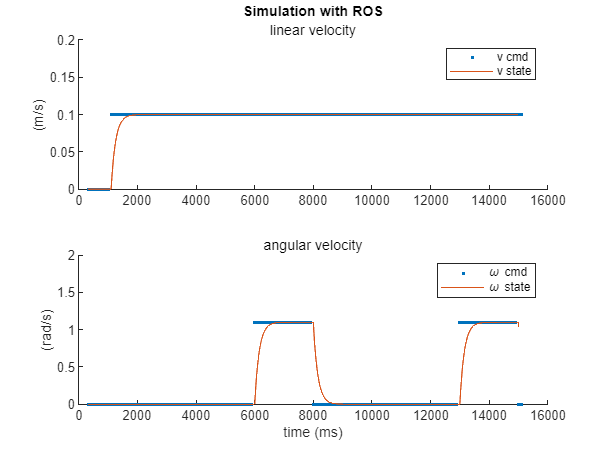

figure
subplot(2,1,1);
    hold on
    plot(t_c(start_c:cutoff_c),cmd(start_c:cutoff_c,1),'.')
    plot(t_t(start_t:cutoff_t),tb_t(start_t:cutoff_t,1))
    hold off
    legend("v cmd","v state")
    ylim([0 .2]);
subtitle("linear velocity")
title("Simulation with ROS")
ylabel("(m/s)")
subplot(2,1,2);
    hold on
    plot(t_c(start_c:cutoff_c),cmd(start_c:cutoff_c,2),'.')
    plot(t_t(start_t:cutoff_t),tb_t(start_t:cutoff_t,2))
    hold off
    legend("\omega cmd","\omega state")
    ylim([0 2]);
subtitle("angular velocity")
% legend('X axis','Y axis','Location','northeast')
ylabel("(rad/s)")
xlabel("time (ms)")

## Open loop trajectory

kp_tuner=  1;
ki_tuner = 1;
eta = 0.1;
simIn = Simulink.SimulationInput("tb_kinematics");
simIn = setModelParameter(simIn,Timeout=30);
simIn = setModelParameter(simIn,StartTime=string(min_t),StopTime=string(max_t));
simIn = simIn.setVariable("eta_var",eta);
simIn = simIn.setVariable("openloop",1);
simIn = simIn.setVariable("kp_tuner",kp_tuner);
simIn = simIn.setVariable("ki_tuner",ki_tuner);
simIn = simIn.setVariable("Ts_s",1/100);
out = sim(simIn); %run simulation, all results returned in "out"
sl_shape = [ out.tb_coordinates.Data(:,1)'; out.tb_coordinates.Data(:,2)' ];

% figure
% subplot(2,1,1);
% plot(t_c(start_c:cutoff_c)-t_start,cmd(start_c:cutoff_c,1))
% title("Simulation with ROS")
% legend('Vel','Location','northeast')
% ylabel("vel (m/s)")
% subtitle("CMD")
% subplot(2,1,2); 
% plot(t_c(start_c:cutoff_c)-t_start,cmd(start_c:cutoff_c,2))
% legend("Rotation",'Location','northeast')
% ylabel("omega (rad/s)")
% xlabel("time (ms)")


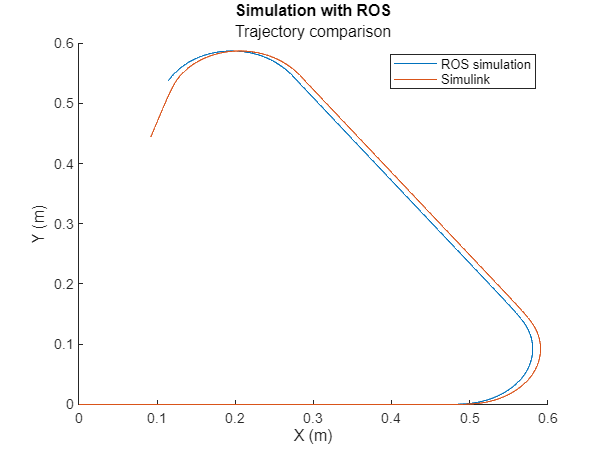


figure
hold on
    plot(pose_ros(start_p:cutoff_p,1),pose_ros(start_p:cutoff_p,2))
    plot(sl_shape(1,:),sl_shape(2,:))
hold off
title("Simulation with ROS")
subtitle("Trajectory comparison")
legend("ROS simulation","Simulink")
% ylim([-3 4])
ylabel("Y (m)")
xlabel("X (m)")

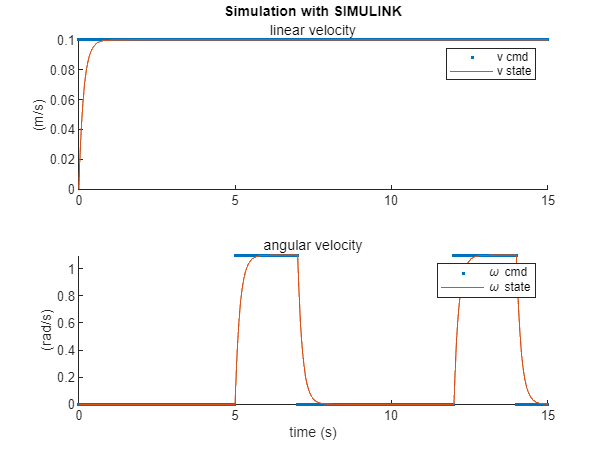

figure
subplot(2,1,1);
    hold on
    plot(out.tout,out.vel_cmd.Data(:,1),".")
    plot(out.tout,out.v_state.Data(:,1))
    hold off
    legend("v cmd","v state")
    % xlim([4 9]);
subtitle("linear velocity")
title("Simulation with SIMULINK")
ylabel("(m/s)")
subplot(2,1,2);
    hold on
     plot(out.tout,out.vel_cmd.Data(:,2)',".")
    plot(out.tout,out.v_state.Data(:,2)')
    hold off
    legend("\omega cmd","\omega state")
    % xlim([4 9]);
subtitle("angular velocity")
% legend('X axis','Y axis','Location','northeast')
ylabel("(rad/s)")
xlabel("time (s)")


function [matrix,t] = pose2mat(msgs)
    matrix = zeros(numel(msgs),2);
    t = zeros(numel(msgs),1);
    for i=1:numel(msgs)
        matrix(i,1) = msgs{i,1}.Pose.Position.X;
        matrix(i,2) = msgs{i,1}.Pose.Position.Y;
        t(i,1) = 10^3* msgs{i,1}.Header.Stamp.Sec + 10^-6 * msgs{i,1}.Header.Stamp.Nsec;
    end

end

function [matrix,t] = vec3tomat(msgs)
    matrix = zeros(numel(msgs),2); % x y magnitude in column
    t = zeros(numel(msgs),1); % time in milliseconds
    for i=1:numel(msgs)
        matrix(i,1) = msgs{i,1}.Vector.X;
        matrix(i,2) = msgs{i,1}.Vector.Y;
        % matrix(i,3) = sqrt(msgs{i,1}.Vector.X^2+msgs{i,1}.Vector.Y^2);
        t(i,1) = 10^3* msgs{i,1}.Header.Stamp.Sec + 10^-6 * msgs{i,1}.Header.Stamp.Nsec;
    end

end

function [matrix,t] = twist2mat(msgs)
    matrix = zeros(numel(msgs),2); % x y magnitude in column
    t = zeros(numel(msgs),1); % time in milliseconds
    for i=1:numel(msgs)
        matrix(i,1) = msgs{i,1}.Twist.Linear.X;
        matrix(i,2) = msgs{i,1}.Twist.Angular.Z;
        % matrix(i,3) = sqrt(msgs{i,1}.Vector.X^2+msgs{i,1}.Vector.Y^2);
        t(i,1) = 10^3* msgs{i,1}.Header.Stamp.Sec + 10^-6 * msgs{i,1}.Header.Stamp.Nsec;
    end

end